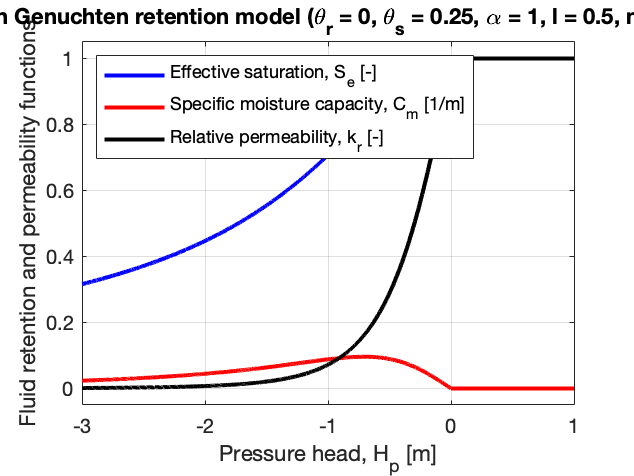

% Initialization
close all
clear
clc

% Material parameters (default in Comsol)
theta_r=0;
theta_s=0.25;

% Constitutive parameters (default in Comsol)
alpha=1;
l=0.5;
n=2;
m=1-1/n;

% Pressure head
vG.H_p=(-3:0.001:1)';
BC.H_p=vG.H_p-1;

% van Genuchten retention model
vG.S_e=(1./(1+abs(alpha*vG.H_p).^n).^m                                     ).*(vG.H_p< 0)+...
       (1                                                                  ).*(vG.H_p>=0);
vG.C_m=(alpha*m/(1-m)*(theta_s-theta_r)*vG.S_e.^(1/m).*(1-vG.S_e.^(1/m)).^m).*(vG.H_p< 0)+...
       (0                                                                  ).*(vG.H_p>=0);
vG.k_r=(vG.S_e.^l.*(1-(1-vG.S_e.^(1/m)).^m).^2                             ).*(vG.H_p< 0)+...
       (1                                                                  ).*(vG.H_p>=0);

% Brooks and Corey retention model
BC.S_e=(1./(abs(alpha*BC.H_p).^n)                             ).*(BC.H_p< -1/alpha)+...
       (1                                                     ).*(BC.H_p>=-1/alpha);
BC.C_m=(-n./BC.H_p*(theta_s-theta_r)*1./(abs(alpha*BC.H_p).^n)).*(BC.H_p< -1/alpha)+...
       (0                                                     ).*(BC.H_p>=-1/alpha);
BC.k_r=(BC.S_e.^(2/n+l+2)                                     ).*(BC.H_p< -1/alpha)+...
       (1                                                     ).*(BC.H_p>=-1/alpha);

% Figure for the van Genuchten retention model
figure
plot(vG.H_p,vG.S_e,'b','LineWidth',2)
hold on
plot(vG.H_p,vG.C_m,'r','LineWidth',2)
plot(vG.H_p,vG.k_r,'k','LineWidth',2)
hold off
grid on
xlim(minmax(vG.H_p'))
ylim([-0.05,1.05])
xlabel('Pressure head, H_p [m]')
ylabel('Fluid retention and permeability functions')
legend('Effective saturation, S_e [-]',...
       'Specific moisture capacity, C_m [1/m]',...
       'Relative permeability, k_r [-]',...
       'Location','NorthWest')
title('van Genuchten retention model (\theta_r = 0, \theta_s = 0.25, \alpha = 1, l = 0.5, n = 2)')

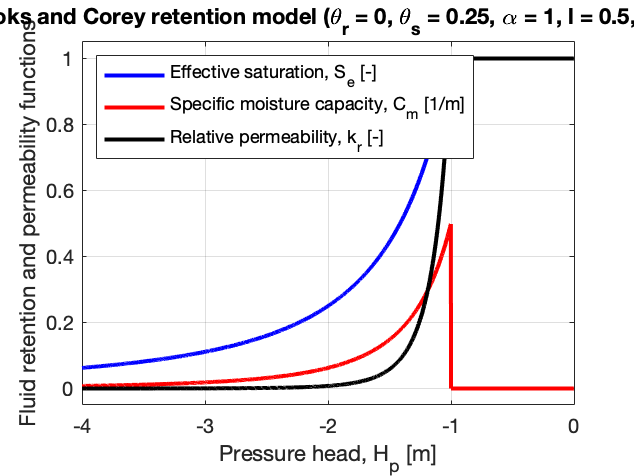


% Figure for the Brooks and Corey retention model
figure
plot(BC.H_p,BC.S_e,'b','LineWidth',2)
hold on
plot(BC.H_p,BC.C_m,'r','LineWidth',2)
plot(BC.H_p,BC.k_r,'k','LineWidth',2)
hold off
grid on
xlim(minmax(BC.H_p'))
ylim([-0.05,1.05])
xlabel('Pressure head, H_p [m]')
ylabel('Fluid retention and permeability functions')
legend('Effective saturation, S_e [-]',...
       'Specific moisture capacity, C_m [1/m]',...
       'Relative permeability, k_r [-]',...
       'Location','NorthWest')
title('Brooks and Corey retention model (\theta_r = 0, \theta_s = 0.25, \alpha = 1, l = 0.5, n = 2)')